# Time-dependent DMRG (tDMRG): Error analysis

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

Here we will implement the **tDMRG (time-dependent density-matrix renormalization group)** method that simulates real-time evolution of a quantum state in an one-dimensional spin systems.

## Exercise (a): Complete the function for tDMRG

There is a function `tDMRG_Ex.m`, which is in the same sub-directory with this script. It is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

## XY spin chain: Real-time evolution of domain wall

As an application of the tDMRG method, we consider (again) the XY spin-1/2 chain of length $L$,


$$\hat{H}_{\mathrm{XY}}
= -\sum_{\ell=1}^{L-1} (\hat{S}_{\ell,x} \hat{S}_{\ell+1,x} + \hat{S}_{\ell,y} \hat{S}_{\ell+1,y})
= -\frac{1}{2} \sum_{\ell=1}^{L-1} (\hat{S}_{\ell,+} \hat{S}_{\ell+1,-} + \hat{S}_{\ell,-} \hat{S}_{\ell+1,+}) .$$


This XY chain model has been already treated in the previous tutorials on the DMRG methods for ground state search. As mentioned there, the system can be mapped onto non-interacting spinless fermions in a tight-binding chain, via the Jordan-Wigner transformation. So this model is analytically solvable.

We defin the nearest-neighbor terms of the Hamiltonian.

clear

% system parameter
J = -1; % coupling strength
L = 50; % number of sites in a chain

% Local operators
[S,I] = getLocalSpace('Spin',1/2);

% nearest-neighbor interaction terms
Hs = cell(1,L-1);
Hs(:) = {J*contract(S(:,:,[1 3]),3,3, ...
    permute(conj(S(:,:,[1 3])),[2 1 3]),3,3)};

Prepare a state of the system at time $t = 0$, where the left half of the chain is up-polarized and the right half is down-polarized:


$$| \Psi (t = 0) \rangle = |\!{\uparrow} \rangle_1 |\!{\uparrow} \rangle_2 \cdots |\!{\uparrow} \rangle_{L/2-1} |\!{\uparrow} \rangle_{L/2} |\!{\downarrow} \rangle_{L/2+1} |\!{\downarrow} \rangle_{L/2+2} \cdots |\!{\downarrow} \rangle_{L-1} |\!{\downarrow} \rangle_{L} .$$


That is, there is a domain wall in between sites $L/2$ and $L/2+1$. The MPS form of $|\Psi(t = 0)\rangle$ can be constructed as follows:

M = cell(1,L);
for itN = (1:L)
    if itN <= (L/2)
        M{itN} = permute([1,0],[1 3 2]);
    else
        M{itN} = permute([0,1],[1 3 2]);
    end
end

Then we evolve the state in real time, via the unitary operator $\exp (- \mathrm{i} \hat{H}_\mathrm{XY} t)$, by using the tDMRG. Here we use the second-order Trotter decomposition: the whole time interval $t \in [0, t_\max]$ is split into small time steps of size $\Delta t$, and the time evolution operator $\exp (- \mathrm{i} \hat{H}_\mathrm{XY} \Delta t)$ is decomposed into three exponential terms, $\exp (- \mathrm{i} \hat{H}_\mathrm{odd} \Delta t/2) \exp (- \mathrm{i} \hat{H}_\mathrm{even} \Delta t) \exp (- \mathrm{i} \hat{H}_\mathrm{odd} \Delta t/2)$, where $\hat{H}_\mathrm{odd}$ ($\hat{H}_\mathrm{even}$) is the sum of interaction terms $\hat{S}_{\ell,+} \hat{S}_{\ell+1,-} + \hat{S}_{\ell,-} \hat{S}_{\ell+1,+}$ for odd (even) $\ell$'s. (Note $\hat{H}_\mathrm{XY} = \hat{H}_\mathrm{odd} + \hat{H}_\mathrm{even}$.) In terms of tensor networks, each exponential term is described as a row of two-site gates; each two-site gate is the exponential of a nearest-neighbor term in the Hamiltonian (multiplied with $-\mathrm{i} \Delta t/2$ or $-\mathrm{i} \Delta t$). 

In this demonstration, we use the following parameters in the tDMRG ($t_\max$ = `tmax`, $\Delta t$ = `dt`):

% tDMRG parameters
Nkeep = 20; % bond dimension
dt = 1/20; % discrete time step size
tmax = 20; % maximum time

The tDMRG function `tDMRG_Ex.m` takes a local operator whose expectation value is measured for every chain site at every time steps. Here we measure magnetization $\langle \Psi (t) | \hat{S}_{\ell,z} | \Psi (t) \rangle$. If the implementation of `tDMRG_Ex.m` were correct, it would run like the example below.

% operator to measure magnetization
Sz = S(:,:,2);

% tDMRG
[ts,M,Ovals,EE,dw] = tDMRG (M,Hs,Sz,Nkeep,dt,tmax);

tDMRG : Real-time evolution with local measurements
N = 50, Nkeep = 20, dt = 0.05, tmax = 20 (400 steps)
22-10-08 21:23:44 | Transform the MPS into right-canonical form.
22-10-08 21:23:44 | Trotter steps: start
22-10-08 21:23:46 | #40/400 : t = 2/20
22-10-08 21:23:47 | #80/400 : t = 4/20
22-10-08 21:23:49 | #120/400 : t = 6/20
22-10-08 21:23:51 | #160/400 : t = 8/20
22-10-08 21:23:53 | #200/400 : t = 10/20
22-10-08 21:23:55 | #240/400 : t = 12/20
22-10-08 21:23:57 | #280/400 : t = 14/20
22-10-08 21:23:59 | #320/400 : t = 16/20
22-10-08 21:24:01 | #360/400 : t = 18/20
22-10-08 21:24:04 | #400/400 : t = 20/20
Elapsed time: 19.62s, CPU time: 90.96s, Avg # of cores: 4.636
22-10-08 21:24:04 | Memory usage : 1.86GiB


The rows of the resulting matrix `Ovals` indicate the magnetization along the chain after every application of a row of time evolution gates. Since we use the second-order Trotter decomposition, every third row of `Ovals` contains the values at physical time steps; that is, `Ovals(3:3:end,:)` are the values at time instances `ts`.

As time evolution operators are complex-valued, `Oval` is complex-valued in general. However, in this tutorial we measure magnetization, i.e., the expectation of the spin-$z$ operator that is Hermitian, any imaginary part of `Ovals` here is numerical noise.

disp(max(abs(imag(Ovals(:))))); % should be double precision noise

   3.0531e-16



Ovals = real(Ovals); % remove noise

Let's analyze $\langle \Psi (t) | \hat{S}_{\ell,z} | \Psi (t) \rangle$ as a function of $\ell$ and $t$. As time goes, the domain wall will be blurred out and spread, since the interaction terms in the Hamiltonian $\hat{H}_\mathrm{XY}$ flip nearest-neighbor spins that are anti-aligned. Indeed, we see that the region in which the magnetization deviates from $\pm 1/2$ propagates linearly in time, and that the velocity is approximately 1. The "wavefronts" of the blurred domain wall (or, say, magnetization fluctuation) don't reach the ends of the system within this time window.

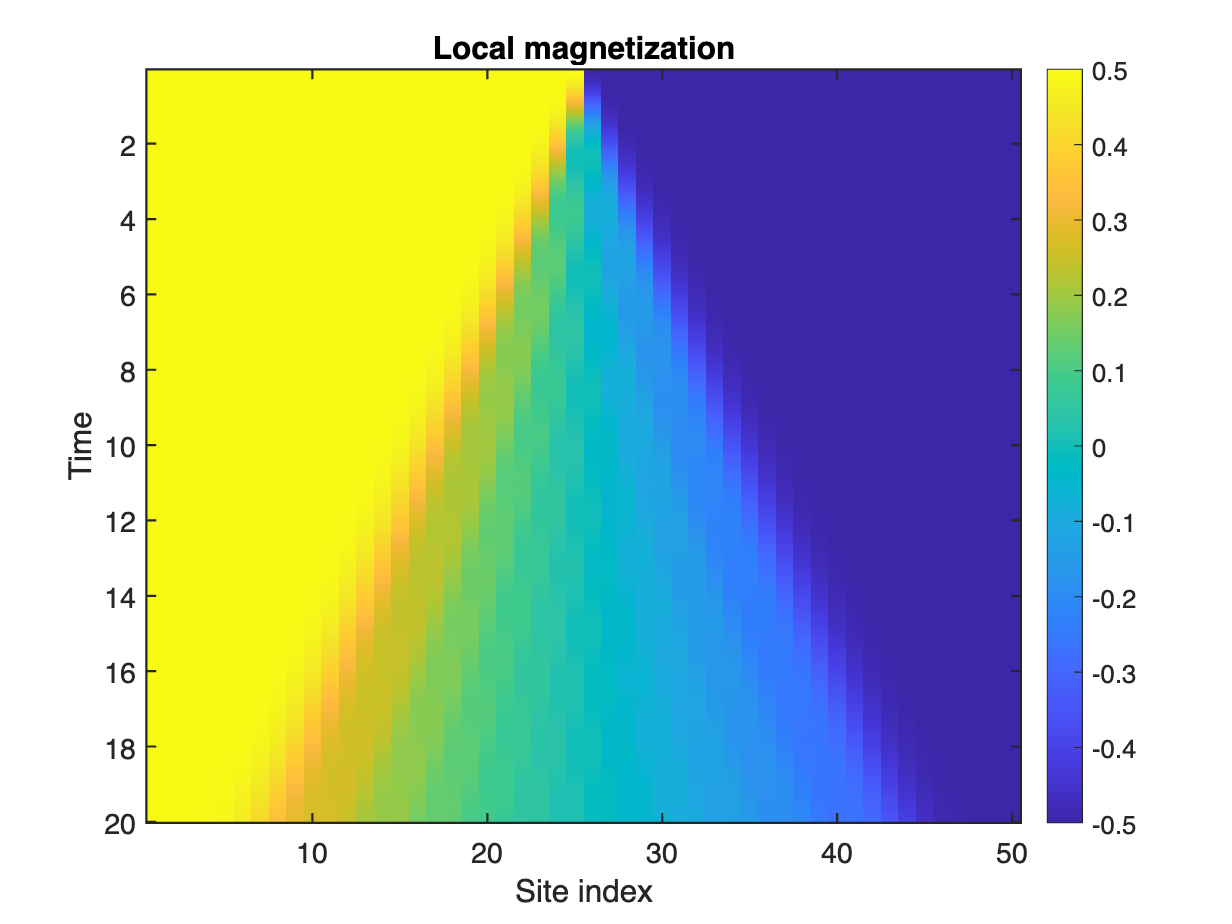

figure;
imagesc([1 L],[ts(1) ts(end)],real(Ovals));
colorbar;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('Site index');
ylabel('Time');
title('Local magnetization');

In the limit of $L \to \infty$, there exists the exact solution of magnetization


$$\langle \Psi (t) | \hat{S}_{\ell,z} | \Psi (t) \rangle = \frac{-1}{2} \sum_{n = 1 - (\ell - L/2)}^{(\ell - L/2) - 1} [ J_n (t) ]^2, \quad \text{for} \,\,\, j > L/2$$


and $\langle \Psi (t) | \hat{S}_{\ell, z} | \Psi (t) \rangle = - \langle \Psi (t) | \hat{S}_{L-\ell,z} | \Psi (t) \rangle$, where $J_n (t)$ is the Bessel function of the first kind; see Eq. (4) in Gobert2005 [[D. Gobert, C. Kollath, U. Schollwöck, and G. Schütz, Phys. Rev. E **71**, 036102 (2005)](https://journals.aps.org/pre/abstract/10.1103/PhysRevE.71.036102)]. (Note that in Gobert2005, the coefficient for the interaction terms is +1, while we use -1 here. This sign difference is not physically relevant, of course, since it can be absorbed into the phase factors of the local basis.)

This analytic solution is effective before the wavefronts are far from the boundary of the system; with our current choice of $t_\max$ it is indeed the case. On the other hand, when the wavefronts reach the boundary, finite-size effects will come in; it will be shown by solving Exercise (c) below.

Let's measure the error of the tDMRG result against the $L \to \infty$ solution.

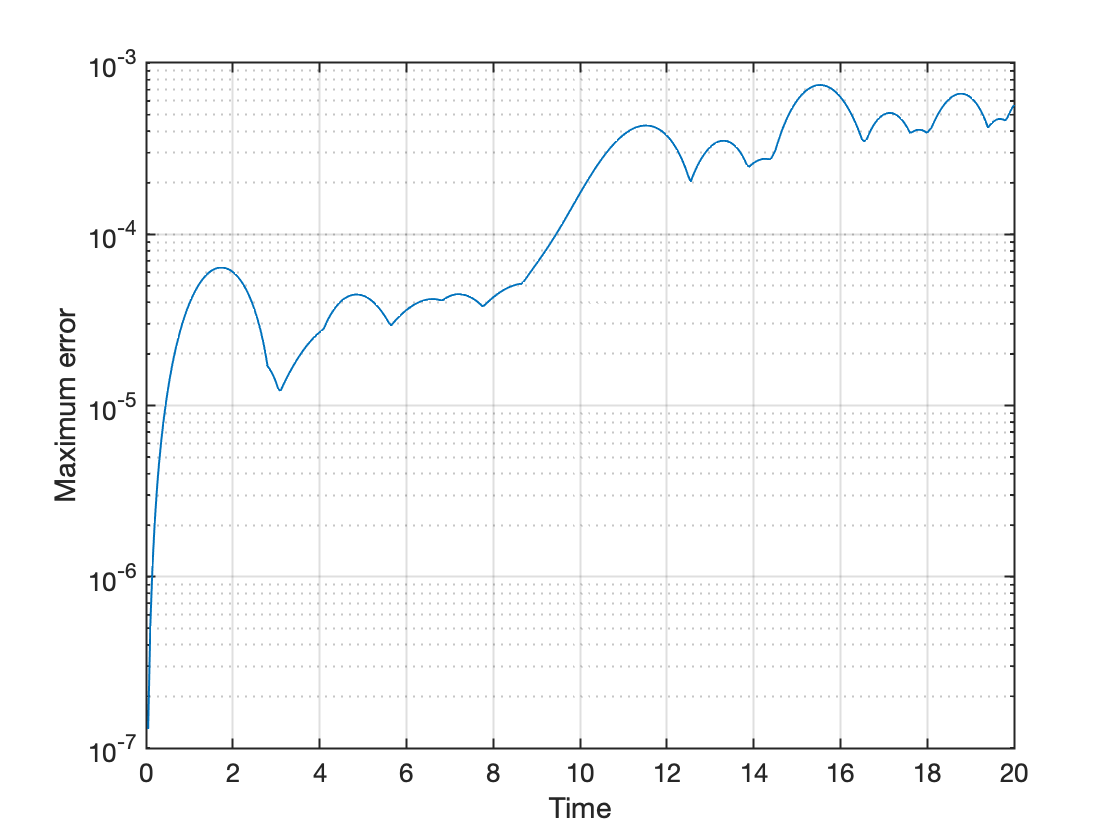

% exact values of magnetization in the infinite chain limit
fvals = zeros(numel(ts),L-1);
for it = (1:size(fvals,2))
    % Bessel function of the 1st kind
    fvals(:,it) = (besselj(it-(L/2),ts(:))).^2;
end
fvals = -0.5*fvals;

Oexact = zeros(numel(ts),L/2); % exact values
for it = (1:(L/2))
    Oexact(:,it) = sum(fvals(:,(L/2-it+1):(it+L/2-1)),2);
end
Oexact = [-fliplr(Oexact),Oexact];

% error between numerical and exact results
figure;
% maximum error along the chain at each time instance
plot(ts,max(abs(Ovals-Oexact),[],2),'LineWidth',1);
set(gca,'FontSize',13,'LineWidth',1,'YScale','log');
grid on;
xlabel('Time');
ylabel('Maximum error');

The error increases gradually with oscillations. The detailed error analysis will be done by solving Exercise (b).

The spread of magnetization fluctuation is accompanied with the growth of the entanglement in the quantum state. We plot the entanglement entropy of the MPS with respect to the bipartition at individual bonds, for different times.

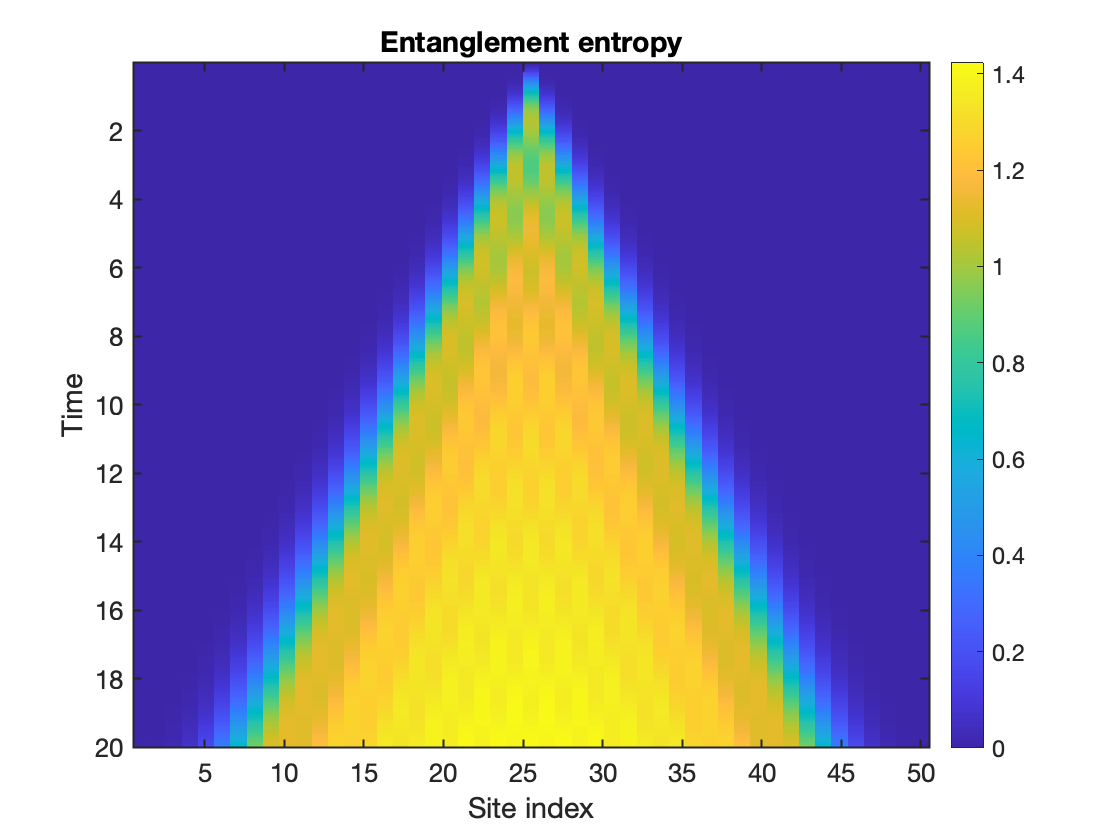

figure;
% every third rows, since each row is a decomposed Trotter
% steps applied to only part of the system
imagesc([1 L],[ts(1) ts(end)],EE(3:3:end,:));
colorbar;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('Site index');
ylabel('Time');
title('Entanglement entropy');

The entanglement entropy is the highest in the central region, and overall increases with time. As the entanglement grows, bond dimensions should also increase to fully describe the MPS. However, for the reason of computational cost, we typically fix the maximum bond dimension, as in this tutorial. Thus the smallest singular values need to be discarded after each singular value decomposition (SVD). The discarded weight is the sum of the squares of such discarded singular values after the SVD (see the documentation of `Tensor/svdTr.m` also). That is, the discarded weight measures the truncation error.

Let's plot the discarded weight. They become finite in the region where the entanglement becomes large. But within this time window, the discarded weight are negligibly small.

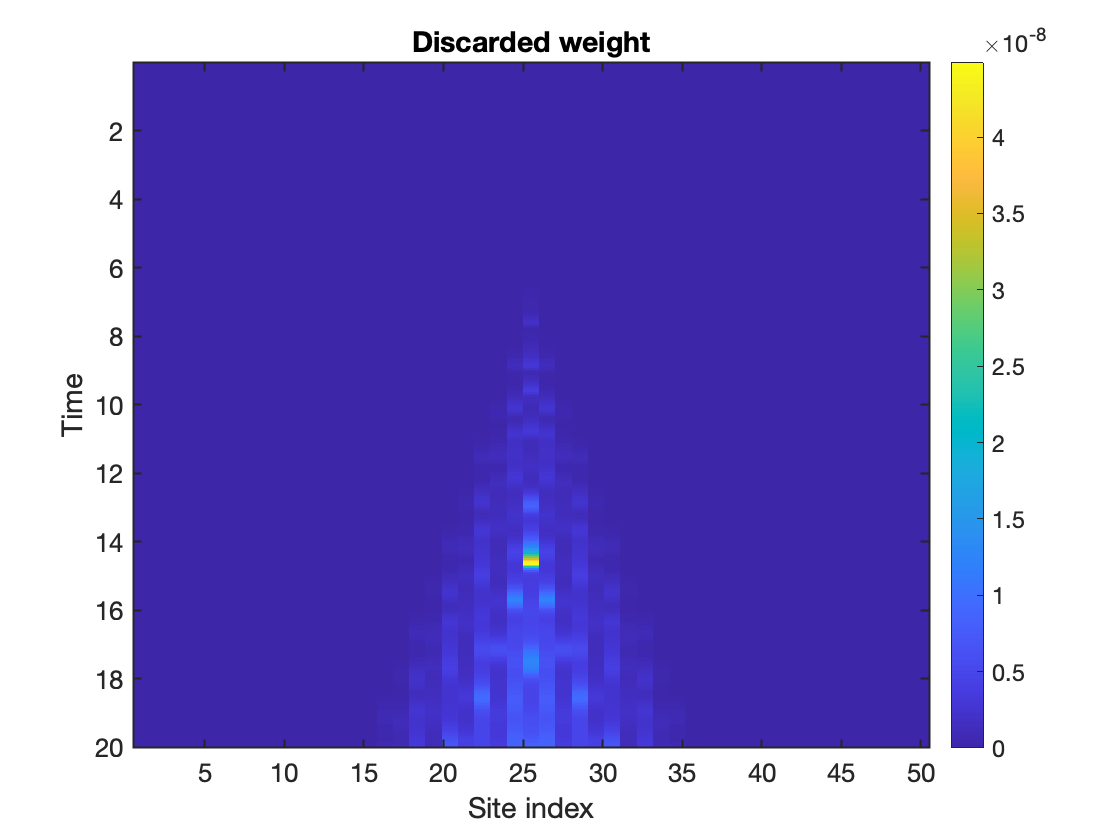

figure;
% sum over every three (decomposed) Trotter steps, to obtain
% the value for every full time step by dt
imagesc([1 L],[ts(1) ts(end)], ...
    squeeze(sum(reshape(dw,[3, size(dw,1)/3, size(dw,2)]),1)));
colorbar;
set(gca,'FontSize',13,'LineWidth',1);
xlabel('Site index');
ylabel('Time');
title('Discarded weight');

## Exercise (b): Change `Nkeep` and `dt`

How the error changes with increasing/decreasing `Nkeep` and `dt`, with fixed `tmax = 20`?

(Hint : Refer to Sec. IV in Gobert2005.)

## Exercise (c): Longer time evolution

Perform the tDMRG calculation for longer time, say, `tmax = 80`. How would the results (magnetization, entanglement entropy, and discarded weight) look like?

## Exercise (d): Different initial state where only one spin is up

Considere a different initial state,


$$|\Psi(t=0)\rangle = \hat{S}_{n,+} |\!{\downarrow},\ldots,{\downarrow}\rangle ,$$


where only one spin at site $n$ is up-polarized and the rest is down-polarized. Perform a tDMRG calculation of local magnetization, and compare the numerical result with the analytic result:


$$\langle \Psi(t) | \hat{S}_{\ell,z}  | \Psi(t) \rangle = \left| \sum_{m=1}^L \frac{2}{L+1} \sin \left(\frac{\pi m}{L+1} n \right)  \sin \left(\frac{\pi m}{L+1} \ell \right) e^{-\mathrm{i} t \cos \left(\frac{\pi m}{L+1} \right)} \right|^2 - \frac{1}{2} \,\, .$$


Actually, with this initial state, the tDMRG simulation can go over longer time window with smaller error, compared with the demonstrated example of the "half-half" initial state. It can be seen by analyzing the entanglement entropy and the discarded weight. **Can you explain why?**